# B

syms t
a=0.01; h0=0.30; theta=pi/4; g = 9.8;
tau = h0.^(5/2).*( 2.*tan(pi/2-theta).^2 )./( 5*a^2*sqrt(2*g) )

tau =   44.538449337485396


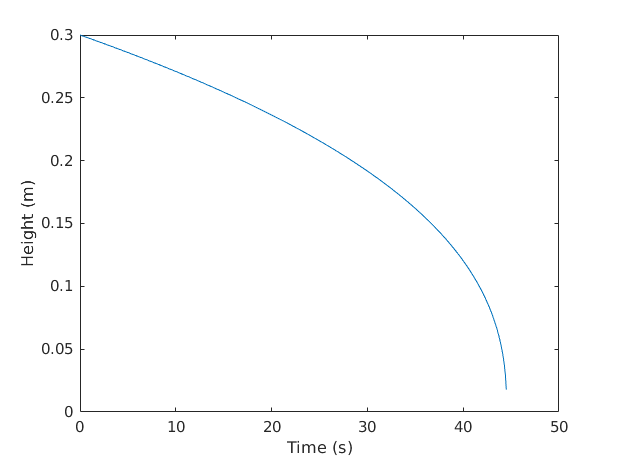

h=@(t) ( h0.^(5/2) - t.*( 5*a^2*sqrt(2*g) )./( 2.*tan(pi/2-theta).^2 ) ).^(2/5);
t = 0:0.1:tau;
plot(t, h(t));
xlabel('Time (s)'); ylabel('Height (m)');
print('eps/topic5_b.eps','-depsc')

# C

theta = linspace(pi/16, 7*pi/16,200);
h0=[0.30; 0.40];
tau= h0.^(5/2).*( 2.*tan(pi/2-theta).^2 )./( 5*a^2*sqrt(2*g) )

tau = 	1.0e+03 *

   1.125671109454026   1.059043542531125   0.998019443578145   0.941987749717082   0.890418482050881   0.842850168997429   0.798879488001947   0.758152689445524   0.720358460732059   0.685221960643150   0.652499809653785   0.621975865062749   0.593457643506319   0.566773279917067   0.541768932927588   0.518306563356265   0.496262025701236   0.475523423235930   0.455989685902868   0.437569337172901   0.420179421709032   0.403744570308848   0.388196182402038   0.373471709511168   0.359514025672640   0.346270872962415   0.333694372058852   0.321740589268230   0.310369152689591   0.299542911247101   0.289227631204480   0.279391725525450   0.270006012079380   0.261043497231347   0.252479181816001   0.244289886887870   0.236454096977495   0.228951818871910   0.221764454186806   0.214874684212229   0.208266365699162   0.201924436414906   0.195834829434579   0.189984395257264   0.184360830940947   0.178952615542540   0.173748951229955   0.168739709503739   0.163915382027844  

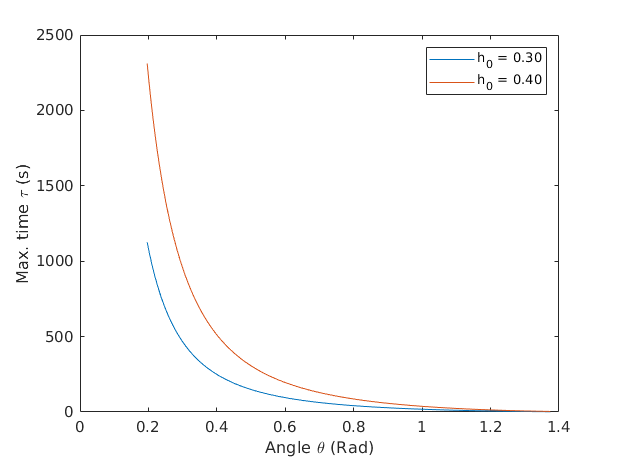

plot(theta, tau(1,:)); hold on;
plot(theta, tau(2,:));
xlabel('Angle \theta (Rad)'); ylabel('Max. time \tau (s)');
legend('h_0 = 0.30', 'h_0 = 0.40')
print('eps/topic5_c.eps','-depsc')

# F

syms t
a=0.01; h0=0.3; theta=pi/4; g=9.8;
tau= h0.^(5/2).*( 2.*tan(pi/2-theta).^2 )./( 5*a^2*sqrt(2*g) )

tau =   44.538449337485396


dhdt=@(t) 2/5*( h0.^(5/2)-t.*(h0^(5/2))./(tau) ).^(-3/5)*( (-h0.^(5/2))./(tau) );
dVdt=@(t) pi.*dhdt(t).*(h(t).*tan(pi/2-theta)).^2;
format long;
V=integral(dVdt,0,tau/2)

V =   -0.015967215238275


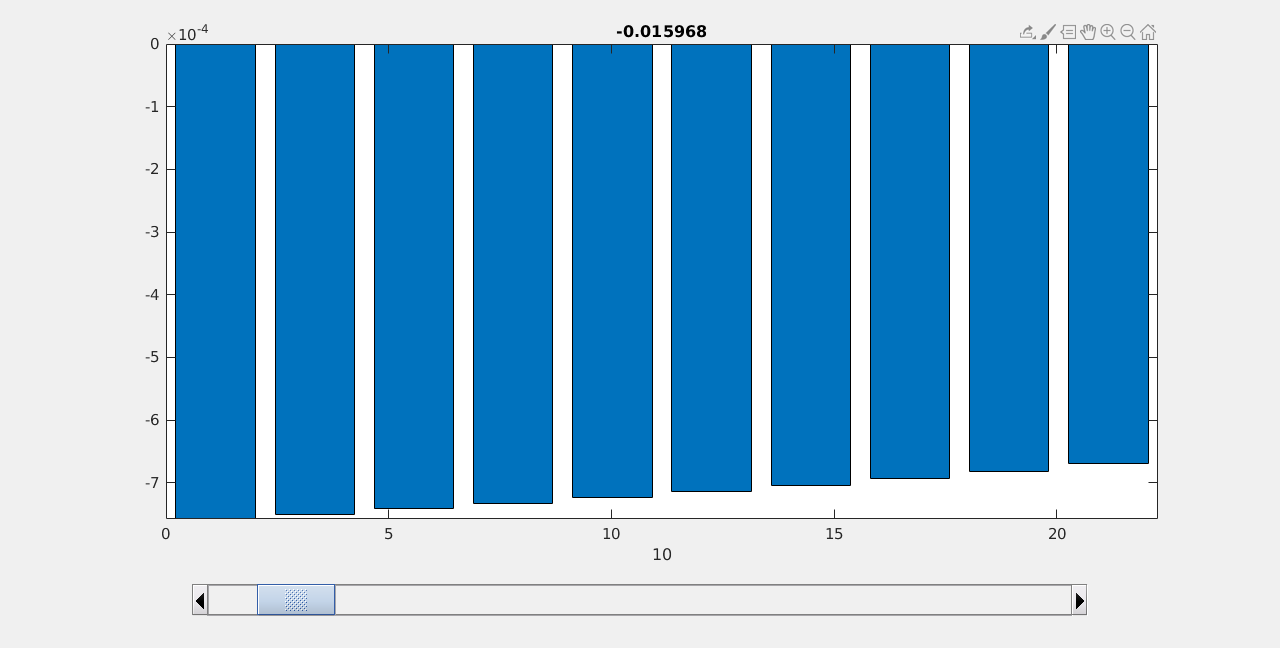

rsums(dVdt, [0,tau/2])